# Boundary-Value Problems and Convergence: A Primer

#### By: Arnaldo Rodriguez-Gonzalez

## The Background

In the language of solving ordinary differential equations, the term "boundary-value problem" indicates that the conditions for which the solution to the differential equation is determined are set at two (or more!) different values of the independent variable in the problem. Compare this with "initial-value problems", in which the conditions are set at only one value of the independent variable.

As an example, consider the following initial-value problem:


$$$$\ddot{x} + x = 0$$



$$x\left(t = 0\right) = a, \quad \dot{x}\left(t =0\right) = b$$


Both conditions needed to pin down the specific solution are set at a specific value of $t$, $0$. And no matter what the values of $a$ and $b$ are, this initial-value problem—this combination of differential equation and conditions to satisfy—always has a solution. 

However, now consider the following *boundary-value* problem:


$$$$\ddot{x} + x = 0$$



$$x\left(t = 0\right) = a, \quad x\left(t =\tau\right) = b$$


This is indeed a boundary-value problem, as we are determining the specific needed solution to this ODE using information at *two* values of $t$: $0$ and $\tau$. And, surprisingly enough, this problem can sometimes have no solution! The absence of a solution, however, will often not prevent a computer from generating something that looks like a possible solution; and so it behooves us, as applied mathematicians, to diagnose when such a thing is happening.

## The Algorithm

This Live Script uses a finite difference method to approximate a solution to the above boundary-value problem. The gist of such a method is that it will generate a solution in the form of an array of $N$ numbers $x_i$ which represent (approximate) values of the solutions at specific values of $t$, $t_i$. It does so by using a two-point central finite difference approximation for $\ddot{x}$:


$$$$\ddot{x}(t_i) = \frac{x(t_{i+1}) - 2x(t_i) + x(t_{i-1})}{h^2}= \frac{x_{i+1} - 2x_i + x_{i-1}}{h^2}$$


$h = \Delta t = t_2 -t_1$ represents the difference between successive values of $t$; it is assumed, for the purposes of this algorithm, that this spacing is uniform. 

We can use this approximation, inserted into the original ODE, to create a set of linear equations for the $x_i$ that can be solved to find the approximation to the solution:

$\frac{x_{i+1} - 2x_i + x_{i-1}}{h^2} + x_i = 0$ when $i\neq 1,N$

$x_1 = a$,    $x_N = b$

Below, you can select $\tau$, $a$, and $b$ and manipulate $N$ to see the behavior of the numerical approximation to the solution of the boundary-value problem, if such a solution exists! 

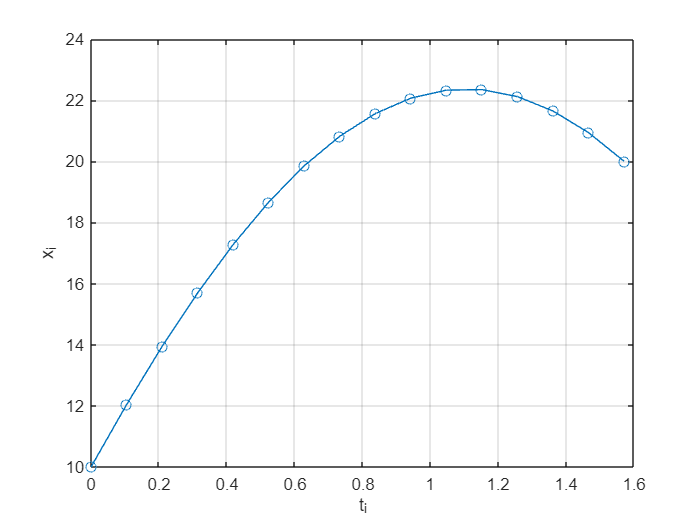

tau = pi/2;
a = 10;
b = 20;
N =16;
t = linspace(0,tau,N);
h = t(2) - t(1);
A = zeros(N);
f = zeros(N,1);
for i = 2:N-1
    A(i,i) = -2/h^2 + 1;
    A(i,i+1) = 1/h^2;
    A(i,i-1) = 1/h^2;
end
A(1,1) = 1;
A(N,N) = 1;
f(1) = a;
f(N) = b;
x = A\f;
plot(t,x,'-o')
grid on
xlabel('t_i')
ylabel('x_i')

## Exercises/Things to Think About

- Set $\tau = \pi$ and pick any non-zero values for $a$ and $b$. How does the approximated solution behave as $N$ gets larger and larger?

- Set $\tau = \frac{\pi}{2}$ for any non-zero values of $a$ and $b$. How does the behavior of this approximation differ as $N$ gets larger from what you saw previously?

- Using $\tau = \pi$, $a$ = 1, and $b = 0$, show that this boundary-value problem has no solution.

- Using $\tau = \frac{\pi}{2}$ and keeping $a$ and $b$ as constants, show that this boundary-value problem always has a solution.

- Either using your own code or editing the code in the Live Script, generate plots of the maximum absolute value of the approximation as a function of $N$ for the following sets of parameters:$\{\tau = \pi, a = 0, b = 1\}$ and $\{\tau = \frac{\pi}{2}, a = 0, b = 1\}$.

- Convergence is a term used to refer to when the characteristics of an approximation stop changing as one increases the "resolution" of the approximation. Which of the above plots implies convergence?

- What statement do you feel you can make about the connection between convergence and the existence of a solution to boundary-value problems?